m = 1;
g = 9.8;
b = 0.1;
w_max = 5; % ограничение частоты вращения
u_max = b * w_max^2;
w0 = sqrt((g * m) / (4 * b));
u0 = 4 * b * w0^2;

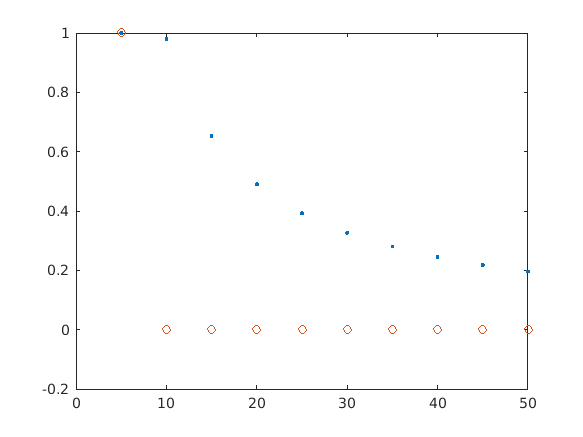

z_star_list = linspace(5, 50, 10);
kd = [];
kp = [];
for i = 1:length(z_star_list)
    z_star = z_star_list(i);
    optimized_vector = fminsearch(@(k)(integrate_arr(u0, m, z_star, k, u_max)), [1 1]);
    kd = [kd, optimized_vector(1)];
    kp = [kp, optimized_vector(2)];
end

plot(z_star_list, kd, '.', z_star_list, kp, 'o') % зависимость оптимальных параметров от z*